# Matrix Computations

# CPSC 5006-EL

## Assignment4

### **Haoliang Sheng 0441916**

### **Q1**

#### **3.4.22**


$$v_1 =\left\lbrack \begin{array}{c}
3\\
-3\\
3\\
-3
\end{array}\right\rbrack ,\textrm{v2}=\left\lbrack \begin{array}{c}
1\\
2\\
3\\
4
\end{array}\right\rbrack$$


#### **(a)**


$$r_{11} ={\left\|v_1 \right\|}_2 =\sqrt{4*9}=6,q_1 =\frac{1}{r_{11} }v_1 =\frac{1}{6}\left\lbrack \begin{array}{c}
3\\
-3\\
3\\
-3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{1}{2}\\
-\frac{1}{2}\\
\frac{1}{2}\\
-\frac{1}{2}
\end{array}\right\rbrack$$



$$r_{12} =\left(v_2 ,q_1 \right)=\frac{1}{2}+2\left(-\frac{1}{2}\right)+3\left(\frac{1}{2}\right)+4\left(-\frac{1}{2}\right)=-1$$



$$\tilde{\;q_2 } =v_2 -r_{12} q_1 =\left\lbrack \begin{array}{c}
1\\
2\\
3\\
4
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\frac{1}{2}\\
-\frac{1}{2}\\
\frac{1}{2}\\
-\frac{1}{2}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\frac{3}{2}\\
\frac{3}{2}\\
\frac{7}{2}\\
\frac{7}{2}
\end{array}\right\rbrack$$



$$r_{22} ={\left\|\tilde{\;q_2 } \right\|}_2 =\sqrt{\frac{9}{4}*2+\frac{49}{4}*2}=\sqrt{29},q_2 =\frac{1}{r_{22} }\tilde{q_2 } =\frac{1}{\sqrt{29}}\left\lbrack \begin{array}{c}
\frac{3}{2}\\
\frac{3}{2}\\
\frac{7}{2}\\
\frac{7}{2}
\end{array}\right\rbrack$$


#### **(b)**


$$Q=\left\lbrack \begin{array}{cc}
q_1  & q_2 
\end{array}\right\rbrack =\frac{1}{2}\left\lbrack \begin{array}{cc}
1 & \frac{3}{\sqrt{29}}\\
-1 & \frac{3}{\sqrt{29}}\\
1 & \frac{7}{\sqrt{29}}\\
-1 & \frac{7}{\sqrt{29}}
\end{array}\right\rbrack ,R=\left\lbrack \begin{array}{cc}
r_{11}  & r_{12} \\
 & r_{22} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
6 & -1\\
0 & \sqrt{29}
\end{array}\right\rbrack$$


### Q2

#### 3.4.27

#### (a)


$$r_{1:k-1,k} \gets {\left(v_{1:k-1} \right)}^T v_k ,\textrm{flop}=2\left(k-1\right)n$$



$$v_k \gets v_k -\left(v_{1:k-1} \right)r_{1:k-1,k} ,\textrm{flop}=2\left(k-1\right)n$$



$$s_{1:k-1} \gets {\left(v_{1:k-1} \right)}^T v_k ,\textrm{flop}=2\left(k-1\right)n$$



$$v_k \gets v_k -\left(v_{1:k-1} \right)s_{1:k-1} ,\textrm{flop}=2\left(k-1\right)n$$



$$r_{1:k-1,k} \gets r_{1:k-1,k} +s_{1:k-1} ,\textrm{flop}=k-1$$



$$r_{\textrm{kk}} \gets {\left\|v_k \right\|}_2 ,\textrm{flop}=2n$$



$$v_k \gets \left(\frac{1}{r_{\textrm{kk}} }\right)v_k ,\textrm{flop}=n$$



$$\textrm{total}\;\textrm{flop}\;\textrm{for}\;\textrm{kth}\;\textrm{time}=8\left(k-1\right)n+3n+k-1\approx 8\textrm{nk}$$


#### (b)


$$\textrm{flops}=\sum_{k=1}^m 8\textrm{nk}=8n\frac{\left(1+m\right)m}{2}\approx 4{\textrm{nm}}^2$$


### Q3

#### 3.4.28

#### (a)

for m=[3 4 5 6 7 8 9 10]
    V = hilb(m);
    [Q, R] = classical_gram_schmidt(V);
    fprintf("Dimension: %d", m);
    fprintf("I - Q'Q: %e", norm(eye(m) - Q'*Q));
    fprintf("V - QR: %e", norm(V - Q*R));
end

Dimension: 3

I - Q'Q: 6.866271e-14

V - QR: 0.000000e+00

Dimension: 4

I - Q'Q: 3.451110e-11

V - QR: 3.925231e-17

Dimension: 5

I - Q'Q: 1.032190e-07

V - QR: 2.775558e-17

Dimension: 6

I - Q'Q: 5.332758e-06

V - QR: 6.206335e-17

Dimension: 7

I - Q'Q: 3.133348e-01

V - QR: 6.850849e-17

Dimension: 8

I - Q'Q: 1.032494e+00

V - QR: 7.479507e-17

Dimension: 9

I - Q'Q: 2.007029e+00

V - QR: 4.734019e-17

Dimension: 10

I - Q'Q: 2.999394e+00

V - QR: 6.515183e-17

#### (b)

for m=[3 4 5 6 7 8 9 10]
    V = hilb(m);
    [Q, R] = modified_gram_schmidt(V);
    fprintf("Dimension: %d", m);
    fprintf("I - Q'Q: %e", norm(eye(m) - Q'*Q));
    fprintf("V - QR: %e", norm(V - Q*R));
end

Dimension: 3

I - Q'Q: 8.612283e-15

V - QR: 0.000000e+00

Dimension: 4

I - Q'Q: 2.984511e-13

V - QR: 5.551115e-17

Dimension: 5

I - Q'Q: 8.492591e-12

V - QR: 5.551115e-17

Dimension: 6

I - Q'Q: 5.814916e-10

V - QR: 2.775558e-17

Dimension: 7

I - Q'Q: 3.829039e-09

V - QR: 5.915766e-17

Dimension: 8

I - Q'Q: 4.375355e-07

V - QR: 6.594918e-17

Dimension: 9

I - Q'Q: 1.700489e-06

V - QR: 6.457371e-17

Dimension: 10

I - Q'Q: 4.155022e-04

V - QR: 7.492457e-17

#### (c)

for m=[3 4 5 6 7 8 9 10]
    V = hilb(m);
    [Q, R] = reorthogonalization(V);
    fprintf("Dimension: %d", m);
    fprintf("I - Q'Q: %e", norm(eye(m) - Q'*Q));
    fprintf("V - QR: %e", norm(V - Q*R));
end

Dimension: 3

I - Q'Q: 2.022546e-16

V - QR: 5.551115e-17

Dimension: 4

I - Q'Q: 1.896146e-16

V - QR: 1.308499e-16

Dimension: 5

I - Q'Q: 3.302972e-16

V - QR: 8.591943e-17

Dimension: 6

I - Q'Q: 1.783775e-16

V - QR: 5.551115e-17

Dimension: 7

I - Q'Q: 2.869709e-16

V - QR: 8.219851e-17

Dimension: 8

I - Q'Q: 2.642104e-16

V - QR: 9.088681e-17

Dimension: 9

I - Q'Q: 3.899998e-16

V - QR: 7.889740e-17

Dimension: 10

I - Q'Q: 3.002226e-16

V - QR: 8.886774e-17

#### (d)

for m=[3 4 5 6 7 8 9 10]
    V = hilb(m);
    [Q, R] = qr(V, 0);
    fprintf("Dimension: %d", m);
    fprintf("I - Q'Q: %e", norm(eye(m) - Q'*Q));
    fprintf("V - QR: %e", norm(V - Q*R));
end

Dimension: 3

I - Q'Q: 2.501259e-16

V - QR: 2.580039e-16

Dimension: 4

I - Q'Q: 7.658024e-16

V - QR: 3.552512e-16

Dimension: 5

I - Q'Q: 9.583549e-16

V - QR: 6.463453e-16

Dimension: 6

I - Q'Q: 8.247379e-16

V - QR: 4.441084e-16

Dimension: 7

I - Q'Q: 6.341502e-16

V - QR: 6.219534e-16

Dimension: 8

I - Q'Q: 6.273268e-16

V - QR: 2.272497e-16

Dimension: 9

I - Q'Q: 1.126719e-15

V - QR: 3.223995e-16

Dimension: 10

I - Q'Q: 1.055787e-15

V - QR: 6.770664e-16

### Q4

A = [3 6 9; 4 8 12];

#### 4.1.14


$${\textrm{AA}}^T =\left\lbrack \begin{array}{ccc}
3 & 6 & 9\\
4 & 8 & 12
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
3 & 4\\
6 & 8\\
9 & 12
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
126 & 168\\
168 & 224
\end{array}\right\rbrack$$



$$\det \left(\left\lbrack \begin{array}{cc}
126-\lambda  & 168\\
168 & 224-\lambda 
\end{array}\right\rbrack \right)=126*224-224\lambda -126\lambda +\lambda^2 -168*168=\left(\lambda -350\right)\lambda$$



$$\sigma_1 =\sqrt{350}=5\sqrt{14},\sigma_2 =0,r=1$$



$$\left({\textrm{AA}}^T -350I\right)u_1 =0,\left\lbrack \begin{array}{cc}
-224 & 168\\
168 & -126
\end{array}\right\rbrack u_1 =0\Leftrightarrow u_1 =\frac{1}{5}\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack$$



$$v_1 =\frac{1}{\sigma_1 }A^T u_1 =\frac{1}{25\sqrt{14}}\left\lbrack \begin{array}{cc}
3 & 4\\
6 & 8\\
9 & 12
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack =\frac{1}{\sqrt{14}}\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack$$



$$\hat{U} =\frac{1}{5}\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack ,\hat{\Sigma} =\left\lbrack \begin{array}{c}
5\sqrt{14}
\end{array}\right\rbrack ,\hat{V} =\frac{1}{\sqrt{14}}\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack$$



$$A=\hat{U} \hat{\Sigma} {\hat{V} }^T =\frac{1}{5}\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
5\sqrt{14}
\end{array}\right\rbrack \frac{1}{\sqrt{14}}\left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack$$



$$A=\sum_{j=1}^r \sigma_j u_j v_j^T =5\sqrt{14}\left(\frac{1}{5}\right)\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack \left(\frac{1}{\sqrt{14}}\right)\left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
3\\
4
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack$$


$A=\hat{U} \hat{\Sigma} {\hat{V} }^T$ and $A=\sum_{j=1}^r \sigma_j u_j v_j^T$ are the same.

#### 4.1.15

[U, S, V] = svd(A, "econ")

U =   -6.0000e-01   8.0000e-01
  -8.0000e-01  -6.0000e-01


S =    1.8708e+01            0
            0   1.1038e-15


V =   -2.6726e-01   9.5141e-01
  -5.3452e-01  -2.7844e-01
  -8.0178e-01  -1.3151e-01


### Q5

#### 4.2.20

A = randn(8, 4);
A(:, 5:6) = A(:, 1:2) + A(:, 3:4);
[Q, R] = qr(randn(6));
A = A*Q;

#### (a)

A

A =    1.8006e+00  -1.3827e+00   7.5407e-01   1.1916e+00  -9.2131e-01   9.7806e-01
  -7.1190e-01  -8.2721e-01  -7.6783e-01   1.3887e+00   3.4733e-01   3.6096e-01
  -1.5849e+00  -5.1495e-01   3.6949e-01   1.2369e+00  -8.0920e-01   4.4398e-01
  -9.7515e-01   1.2749e+00  -4.2530e-01  -1.4033e+00  -2.8775e-01  -2.7467e-01
  -3.7988e+00   3.1514e-01  -7.6148e-01   8.4647e-01  -1.6337e+00   8.3545e-01
  -3.3808e-01   4.8169e-01  -1.0965e+00  -4.8740e-01   1.1813e+00  -5.2930e-01
   1.2723e+00  -5.3754e-01   1.5786e+00   2.8530e-01  -2.1017e-01  -1.2903e-01
   1.6145e+00  -3.4943e-01  -1.1445e+00  -3.1882e-03   2.3296e+00  -7.0652e-01


I can't tell  A has rank 4 by looking at it.

#### (b)

format short e
svd(A)

ans =    5.6870e+00
   4.2503e+00
   2.9333e+00
   1.1130e+00
   8.5976e-16
   1.7753e-16


4 of the singular values are "large", 2 of the singular values "tiny".

#### (c)

rank(A)

ans =      4


#### (d)

rank(A, 1e-17)

ans =      6


### Q6

#### 4.3.4


$$\Sigma =\left\lbrack \begin{array}{cc}
\hat{\Sigma}  & 0\\
0 & 0
\end{array}\right\rbrack ,\hat{\Sigma} =\textrm{diag}\left\lbrace \sigma_1 ,\cdots ,\sigma_r \right\rbrace$$



$${\hat{\Sigma} }^{-1} =\textrm{diag}\left\lbrace \frac{1}{\sigma_1 },\frac{1}{\sigma_2 },\cdots ,\frac{1}{\sigma_r }\right\rbrace$$


Since $\left\lbrack \begin{array}{cc}
\hat{\Sigma}  & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
{\hat{\Sigma} }^{-1}  & 0\\
0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
\sigma_1  &  &  &  &  & 0\\
 & \ddots  &  &  &  & \\
 &  & \sigma_n  &  &  & \\
 &  &  & 0 &  & \\
 &  &  &  & \ddots  & \\
0 &  &  &  &  & 0
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccccc}
\frac{1}{\sigma_1 } &  &  &  &  & 0\\
 & \ddots  &  &  &  & \\
 &  & \frac{1}{\sigma_r } &  &  & \\
 &  &  & 0 &  & \\
 &  &  &  & \ddots  & \\
0 &  &  &  &  & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
1 &  &  &  &  & 0\\
 & \ddots  &  &  &  & \\
 &  & 1 &  &  & \\
 &  &  & 0 &  & \\
 &  &  &  & \ddots  & \\
0 &  &  &  &  & 0
\end{array}\right\rbrack$

Let $\Sigma v_i =\sigma_i u_i$, if $i=r+1\cdots m$, $\Sigma v_i =0$, then $\left\lbrack \begin{array}{cc}
\hat{\Sigma}  & 0\\
0 & 0
\end{array}\right\rbrack v_i =\sigma_i u_i$, $u_i =\frac{1}{\sigma_i }\left\lbrack \begin{array}{cc}
\hat{\Sigma}  & 0\\
0 & 0
\end{array}\right\rbrack v_i$

then $\left\lbrack \begin{array}{cc}
{\hat{\Sigma} }^{-1}  & 0\\
0 & 0
\end{array}\right\rbrack u_i =\left\lbrack \begin{array}{cc}
{\hat{\Sigma} }^{-1}  & 0\\
0 & 0
\end{array}\right\rbrack \frac{1}{\sigma_i }\left\lbrack \begin{array}{cc}
\hat{\Sigma}  & 0\\
0 & 0
\end{array}\right\rbrack v_i =\frac{1}{\sigma_i }\left\lbrack \begin{array}{cccccc}
1 &  &  &  &  & 0\\
 & \ddots  &  &  &  & \\
 &  & 1 &  &  & \\
 &  &  & 0 &  & \\
 &  &  &  & \ddots  & \\
0 &  &  &  &  & 0
\end{array}\right\rbrack v_i =\frac{1}{\sigma_i }v_i$, if $i=r+1\cdots n$, $\left\lbrack \begin{array}{cc}
{\hat{\Sigma} }^{-1}  & 0\\
0 & 0
\end{array}\right\rbrack u_i =0$

So if $\Sigma v_i =\sigma_i u_i$, then $\left\lbrack \begin{array}{cc}
{\hat{\Sigma} }^{-1}  & 0\\
0 & 0
\end{array}\right\rbrack u_i =\frac{1}{\sigma_i }v_i$

So $\Sigma^{\dagger} =\left\lbrack \begin{array}{cc}
{\hat{\Sigma} }^{-1}  & 0\\
0 & 0
\end{array}\right\rbrack$

#### 4.3.8


$$A=\sum_{i=1}^r \sigma_i u_i v_i^T$$



$$\begin{array}{l}
A^{\dagger} ={\left({U\Sigma V}^T \right)}^{\dagger} ={\left(V^T \right)}^{\dagger} \Sigma^{\dagger} U^{\dagger} =V\Sigma^{\dagger} U^T \\
=\left\lbrack \begin{array}{cccccc}
u_1  & \cdots  & u_r  & u_{r+1}  & \cdots  & u_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccccc}
\frac{1}{\sigma_1 } &  &  &  &  & 0\\
 & \ddots  &  &  &  & \\
 &  & \frac{1}{\sigma_r } &  &  & \\
 &  &  & 0 &  & \\
 &  &  &  & \ddots  & \\
0 &  &  &  &  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1^T \\
\vdots \\
u_r^T \\
u_{r+1}^T \\
\vdots \\
u_n^T 
\end{array}\right\rbrack =\sum_{i=1}^r {\sigma_i }^{-1} v_i u_i^T +\sum_{r+1}^n 0*v_i u_i^T =\sum_{i=1}^r {\sigma_i }^{-1} v_i u_i^T 
\end{array}$$


### Q7

#### 4.3.9

A = [1 2; 2 4; 3 6];
b = [1;1;1];

#### (a)


$$A^T A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
2 & 4 & 6
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 2\\
2 & 4\\
3 & 6
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
14 & 28\\
28 & 56
\end{array}\right\rbrack$$



$$\det \left(\left\lbrack \begin{array}{cc}
14-\lambda  & 28\\
28 & 56-\lambda 
\end{array}\right\rbrack \right)=\left(14-\lambda \right)\left(56-\lambda \right)-{28}^2 =\left(\lambda -70\right)\lambda$$



$$\sigma_1 =\sqrt{70},\sigma_2 =0,r=1$$



$$\left(A^T A-70I\right)v_1 =0,\left\lbrack \begin{array}{cc}
-56 & 28\\
28 & -14
\end{array}\right\rbrack v_1 =0\Leftrightarrow v_1 =\frac{1}{\sqrt{5}}\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack$$


$u_1 =\frac{1}{\sigma_1 }{\textrm{Av}}_1 =\frac{1}{\sqrt{70}}\left\lbrack \begin{array}{cc}
1 & 2\\
2 & 4\\
3 & 6
\end{array}\right\rbrack \frac{1}{\sqrt{5}}\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack =\frac{\sqrt{14}}{70}\left\lbrack \begin{array}{c}
5\\
10\\
15
\end{array}\right\rbrack$, normalize $u_1 =\frac{1}{\sqrt{14}}\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack$


$$\hat{U} =\frac{1}{\sqrt{14}}\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack ,\hat{\Sigma} =\left\lbrack \begin{array}{c}
\sqrt{70}
\end{array}\right\rbrack ,\hat{V} =\frac{1}{\sqrt{5}}\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack$$



$$A=\hat{U} \hat{\Sigma} {\hat{V} }^T =\frac{1}{\sqrt{14}}\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\sqrt{70}
\end{array}\right\rbrack \frac{1}{\sqrt{5}}\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 2
\end{array}\right\rbrack$$



$$A=\sum_{j=1}^r \sigma_j u_j v_j^T =\sqrt{70}\left(\frac{1}{\sqrt{14}}\right)\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack \left(\frac{1}{\sqrt{5}}\right)\left\lbrack \begin{array}{cc}
1 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 2
\end{array}\right\rbrack$$


[U, S, V] = svd(A, "econ")

U =   -2.6726e-01   9.5141e-01
  -5.3452e-01  -2.7844e-01
  -8.0178e-01  -1.3151e-01


S =    8.3666e+00            0
            0   4.1137e-16


V =   -4.4721e-01   8.9443e-01
  -8.9443e-01  -4.4721e-01


#### (b)


$$A^{\dagger} =V\Sigma^{\dagger} U^T =\frac{1}{\sqrt{5}}\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\frac{1}{\sqrt{70}}
\end{array}\right\rbrack \left(\frac{1}{\sqrt{14}}\right)\left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack =\frac{1}{70}\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
2 & 4 & 6
\end{array}\right\rbrack$$



$$A^{\dagger} =\sum_{j=1}^r \frac{1}{\sigma_j }v_j u_j^T =\frac{1}{\sqrt{70}}\left(\frac{1}{\sqrt{5}}\right)\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack \left(\frac{1}{\sqrt{14}}\right)\left\lbrack \begin{array}{ccc}
1 & 2 & 3
\end{array}\right\rbrack =\frac{1}{70}\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
2 & 4 & 6
\end{array}\right\rbrack$$


pinv(A)

ans =    1.4286e-02   2.8571e-02   4.2857e-02
   2.8571e-02   5.7143e-02   8.5714e-02


#### (c)


$$\begin{array}{l}
\min {\left\|b-\textrm{Ax}\right\|}_2 ={\left\|b-{\textrm{AA}}^{\dagger} b\right\|}_2 ={\left\|\left(I-{\textrm{AA}}^{\dagger} \right)b\right\|}_2 ={\left\|\left(\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack -\left\lbrack \begin{array}{cc}
1 & 2\\
2 & 4\\
3 & 6
\end{array}\right\rbrack \frac{1}{70}\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
2 & 4 & 6
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack \right\|}_2 \\
={\left\|\left(\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack -\frac{1}{70}\left\lbrack \begin{array}{ccc}
5 & 10 & 15\\
10 & 20 & 30\\
15 & 30 & 45
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack \right\|}_2 ={\left\|\left\lbrack \begin{array}{ccc}
\frac{13}{14} & -\frac{1}{7} & -\frac{3}{14}\\
-\frac{1}{7} & \frac{5}{7} & -\frac{3}{7}\\
-\frac{3}{14} & -\frac{3}{7} & \frac{5}{14}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack \right\|}_2 ={\left\|\left\lbrack \begin{array}{c}
\frac{4}{7}\\
\frac{1}{7}\\
-\frac{2}{7}
\end{array}\right\rbrack \right\|}_2 \\
=\sqrt{{\left(\frac{4}{7}\right)}^2 +{\left(\frac{1}{7}\right)}^2 +{\left(-\frac{2}{7}\right)}^2 }=\sqrt{\frac{3}{7}}
\end{array}$$


norm(b-A*pinv(A)*b)

ans =    6.5465e-01


#### (d)


$$\textrm{Let}\;N\left(A\right)=\left\lbrack \begin{array}{c}
n_1 \\
n_2 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{cc}
1 & 2\\
2 & 4\\
3 & 6
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
n_1 \\
n_2 
\end{array}\right\rbrack =0\Leftrightarrow n_1 +2n_2 =0\Leftrightarrow n_1 =-2n_2$$



$$N\left(A\right)=a\left\lbrack \begin{array}{c}
2\\
-1
\end{array}\right\rbrack ,a\in R-\left\lbrace 0\right\rbrace$$


#### (e)


$$x=A^{\dagger} b=\frac{1}{70}\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
2 & 4 & 6
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack =\frac{1}{70}\left\lbrack \begin{array}{c}
6\\
12
\end{array}\right\rbrack$$


pinv(A)*b

ans =    8.5714e-02
   1.7143e-01


### Q8

#### 4.3.10

A = [1 2 3; 2 4 6];
pinv(A)

ans =    1.4286e-02   2.8571e-02
   2.8571e-02   5.7143e-02
   4.2857e-02   8.5714e-02


svd(A*pinv(A))

ans =    1.0000e+00
   4.9252e-17


svd(pinv(A)*A)

ans =    1.0000e+00
   9.2332e-17
   2.4978e-17


Since A has a rank of 1, ${\mathrm{AA}}^{\dagger}$or $A^{\dagger} A$ has a rank of 1. 

So each of them has only one "large" singular value, which is 1, other singular values are very small.

### Q9

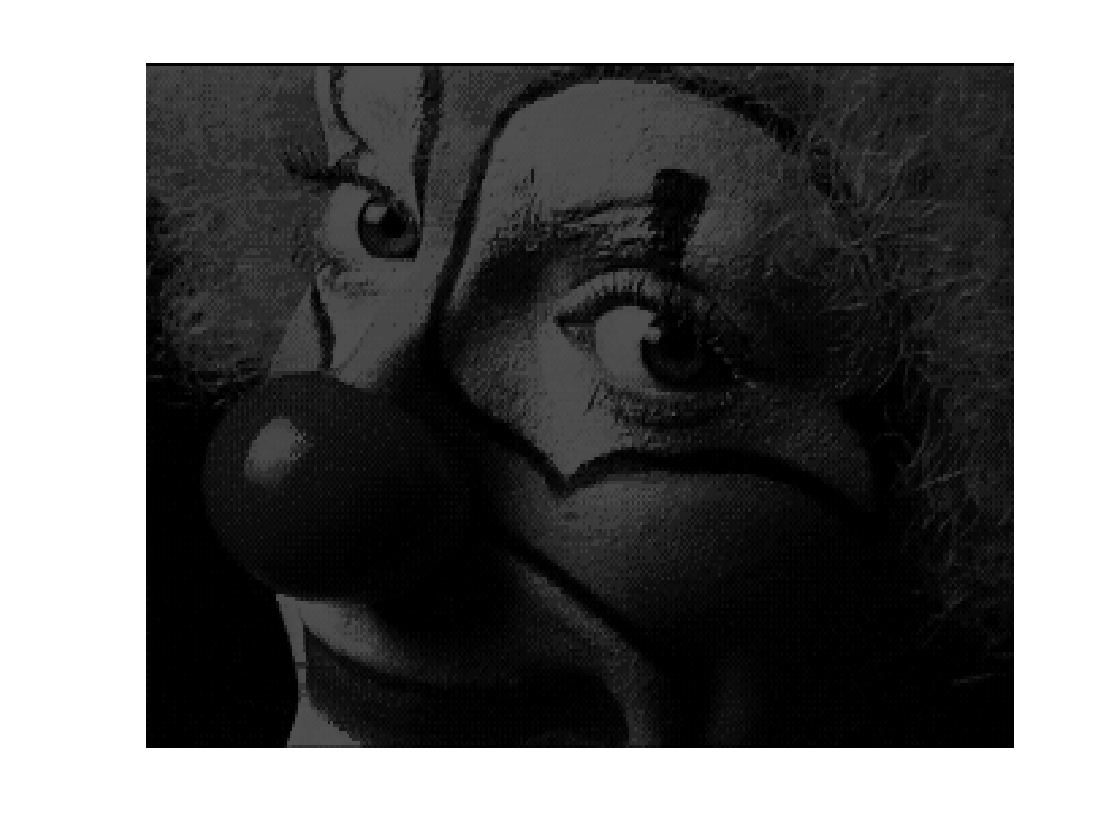

load('clown.mat');
image(X);
colormap("gray"); axis off;

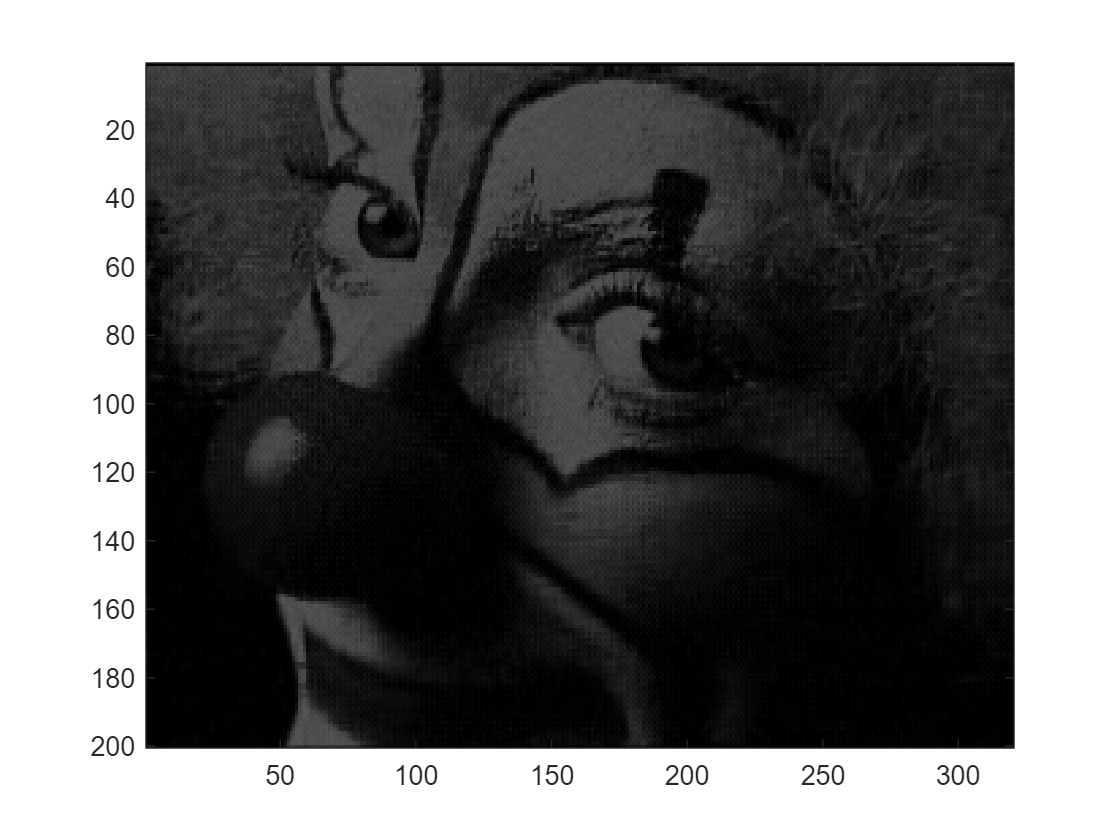

[U, S, V] = svd(X);
n = 50;
Xk = U(:, 1:n) * S(1:n, 1:n) * V(:, 1:n)';
image(Xk);

If we take rank of 15, it still have a decent looking.

If  we take a very low rank like 3, the image will blurred.

#### 1)


$$A=\hat{U} \hat{\Sigma} {\hat{V} }^T$$


$A$ has has dimension nxm.

$\hat{U}$ has dimension nxr, needs to store nr numbers.

$\hat{\Sigma}$ has dimension rxr, and it is diagnal, needs to store r numbers.

${\hat{V} }^T$ has dimension rxm, needs to store mr numbers.

$\textrm{nr}+r+\textrm{rm}=r\left(m+n+1\right)$.

#### 2)

Original image needs to store $n\times m=200\times 320=64000$ numbers.

When r = 30, image needs to store $n\times m=30\left(200+320+1\right)=15630$ numbers.

When r = 15, image needs to store $n\times m=15\left(200+320+1\right)=7815$ numbers.

The lower-rank we choose, the lower storage we need, but the image will be more blurry.

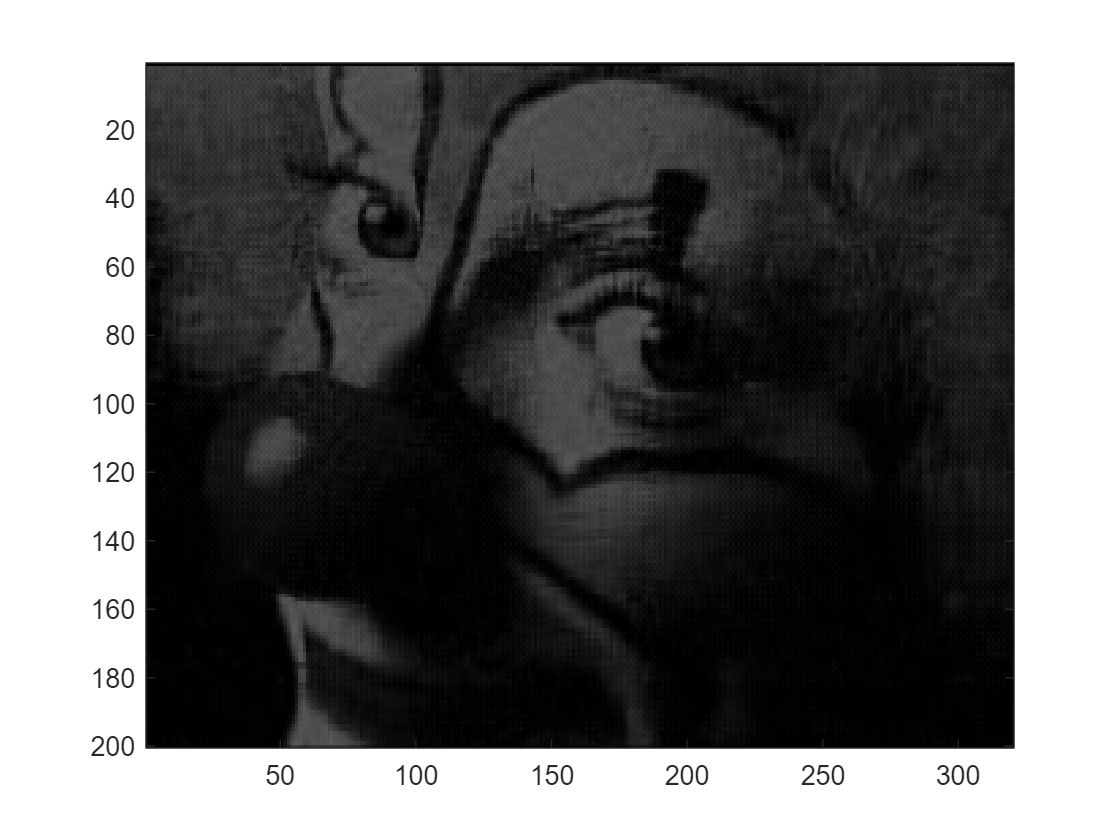

n = 30;
Xk = U(:, 1:n) * S(1:n, 1:n) * V(:, 1:n)';
image(Xk);

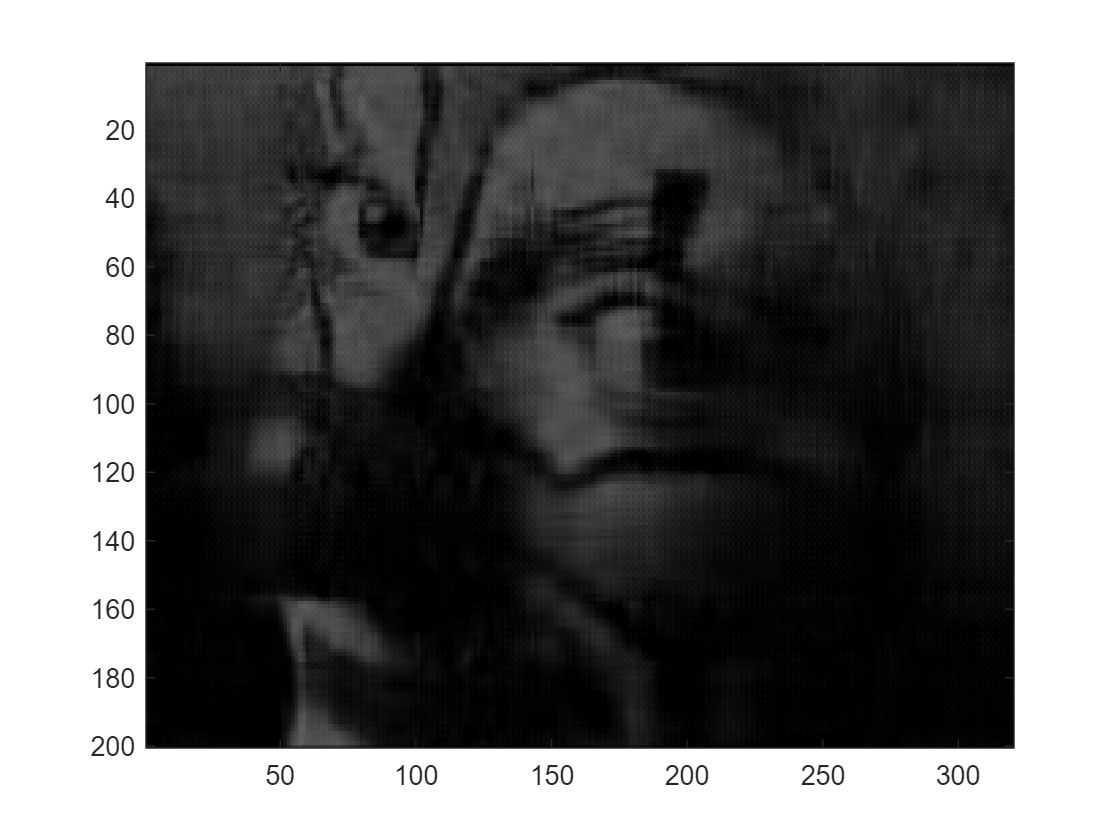

n = 15;
Xk = U(:, 1:n) * S(1:n, 1:n) * V(:, 1:n)';
image(Xk);